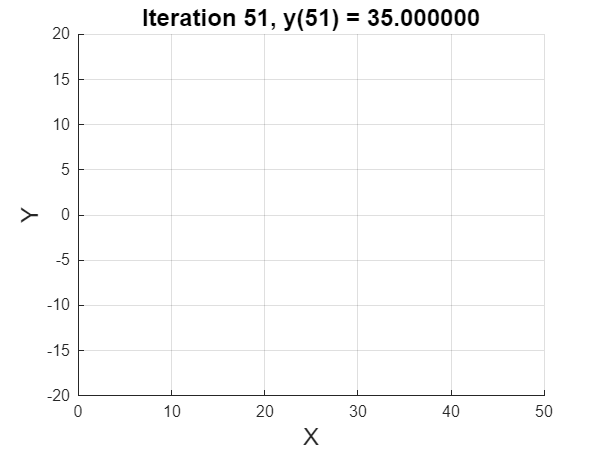

Iteration 1, y(1) = 0.000000
Iteration 2, y(2) = 0.700000
Iteration 3, y(3) = 1.400000
Iteration 4, y(4) = 2.100000
Iteration 5, y(5) = 2.800000
Iteration 6, y(6) = 3.500000
Iteration 7, y(7) = 4.200000
Iteration 8, y(8) = 4.900000
Iteration 9, y(9) = 5.600000
Iteration 10, y(10) = 6.300000
Iteration 11, y(11) = 7.000000
Iteration 12, y(12) = 7.700000
Iteration 13, y(13) = 8.400000
Iteration 14, y(14) = 9.100000
Iteration 15, y(15) = 9.800000
Iteration 16, y(16) = 10.500000
Iteration 17, y(17) = 11.200000
Iteration 18, y(18) = 11.900000
Iteration 19, y(19) = 12.600000
Iteration 20, y(20) = 13.300000
Iteration 21, y(21) = 14.000000
Iteration 22, y(22) = 14.700000
Iteration 23, y(23) = 15.400000
Iteration 24, y(24) = 16.100000
Iteration 25, y(25) = 16.800000
Iteration 26, y(26) = 17.500000
Iteration 27, y(27) = 18.200000
Iteration 28, y(28) = 18.900000
Iteration 29, y(29) = 19.600000
Iteration 30, y(30) = 20.300000
Iteration 31, y(31) = 21.000000
Iteration 32, y(32) = 21.700000
Iteration

clc;
clear;

% Initialization steps
clc;    % Clear the command window.
close all;  % Close all figures (except those of imtool.)
clear;  % Erase all existing variables. Or clearvars if you want.
workspace;  % Make sure the workspace panel is showing.
format long g;
format compact;
fontSize = 13;

% Define oscillation parameters
t = 0:50;
y = t*0.7;

% Define graphics parameters
rectangleHeight = 10;
rectangleWidth = 10;
rectangleX1 = -5;
lineX = 15;

% Set up axes
grid on;
ylim([-20, 20]);
xlim([0, 50]);
xlabel('X', 'FontSize', 15);
ylabel('Y', 'FontSize', 15);

% Number of lines to split the rectangle
numLines = 5;

% Start the movement
for k = 1:length(y)
    caption = sprintf('Iteration %d, y(%d) = %f', k, k, y(k));
    fprintf('%s\n', caption);

    % Place a rectangle at the current y location
    r = rectangle('Position', [y(k), rectangleX1, rectangleWidth, rectangleHeight]);
    title(caption, 'FontSize', 15);

    % Calculate line positions based on the rectangle's position
    linePositions = y(k) + rectangleWidth / (numLines + 1) * (1:numLines);

    % Draw lines
    for j = 1:numLines
        hLine(j) = line([linePositions(j), linePositions(j)], [-3, 3], 'LineWidth', 1, 'Color', 'b');
    end

    drawnow;

    % Wait long enough to see it at this location
    pause(0.3);
    % Delete the rectangle and lines
    delete(r);
    delete(hLine);

end

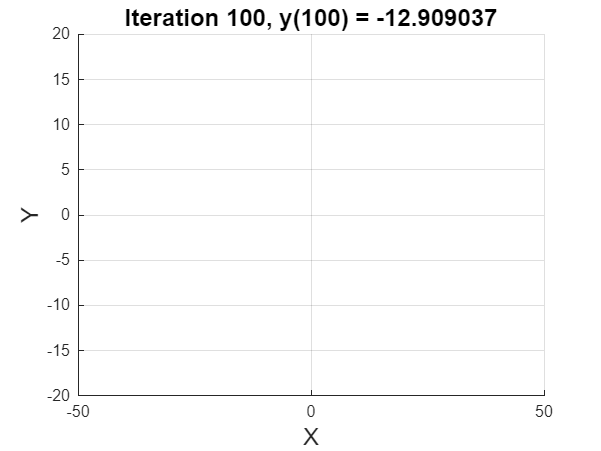

Iteration 1, y(1) = 0.000000
Iteration 2, y(2) = 2.985838
Iteration 3, y(3) = 5.942024
Iteration 4, y(4) = 8.839204
Iteration 5, y(5) = 11.648607
Iteration 6, y(6) = 14.342333
Iteration 7, y(7) = 16.893634
Iteration 8, y(8) = 19.277172
Iteration 9, y(9) = 21.469280
Iteration 10, y(10) = 23.448188
Iteration 11, y(11) = 25.194245
Iteration 12, y(12) = 26.690111
Iteration 13, y(13) = 27.920932
Iteration 14, y(14) = 28.874485
Iteration 15, y(15) = 29.541301
Iteration 16, y(16) = 29.914759
Iteration 17, y(17) = 29.991149
Iteration 18, y(18) = 29.769714
Iteration 19, y(19) = 29.252651
Iteration 20, y(20) = 28.445097
Iteration 21, y(21) = 27.355069
Iteration 22, y(22) = 25.993393
Iteration 23, y(23) = 24.373590
Iteration 24, y(24) = 22.511747
Iteration 25, y(25) = 20.426351
Iteration 26, y(26) = 18.138113
Iteration 27, y(27) = 15.669754
Iteration 28, y(28) = 13.045788
Iteration 29, y(29) = 10.292271
Iteration 30, y(30) = 7.436547
Iteration 31, y(31) = 4.506975
Iteration 32, y(32) = 1.532647
I

clc;
clear;

% Initialization steps
clc;    % Clear the command window.
close all;  % Close all figures (except those of imtool.)
clear;  % Erase all existing variables. Or clearvars if you want.
workspace;  % Make sure the workspace panel is showing.
format long g;
format compact;
fontSize = 13;

% Define oscillation parameters
period = 10;
t = linspace(0, 5 * pi, 100);
y = 30 * sin(2 * pi * t / period);

% Define graphics parameters
rectangleHeight = 10;
rectangleWidth = 15;
rectangleX1 = -5;
lineX = 15;

% Set up axes
grid on;
ylim([-20, 20]);
xlim([-50, 50]);
xlabel('X', 'FontSize', 15);
ylabel('Y', 'FontSize', 15);

% Number of lines to split the rectangle
numLines = 5;

% Start the movement
for k = 1:length(y)
    caption = sprintf('Iteration %d, y(%d) = %f', k, k, y(k));
    fprintf('%s\n', caption);

    % Place a rectangle at the current y location
    r = rectangle('Position', [y(k), rectangleX1, rectangleWidth, rectangleHeight]);
    title(caption, 'FontSize', 15);

    % Calculate line positions based on the rectangle's position
    linePositions = y(k) + rectangleWidth / (numLines + 1) * (1:numLines);

    % Draw lines
    for j = 1:numLines
        hLine(j) = line([linePositions(j), linePositions(j)], [-3, 3], 'LineWidth', 1, 'Color', 'b');
    end

    drawnow;

    % Wait long enough to see it at this location
    pause(0.3);
    % Delete the rectangle and lines
    delete(r);
    delete(hLine);

end